% Cargar datos
data = readtable('Five_times_Kinematics_HT_Query_final.xlsx');


fprintf('Dimensiones del dataset: %d filas x %d columnas\n', size(data,1), size(data,2));

Dimensiones del dataset: 46 filas x 81 columnas


disp('Variables del dataset:');

Variables del dataset:


disp(data.Properties.VariableNames);

    {'reclutado'}    {'AgeGroup'}    {'BMI_Value'}    {'GroupName'}    {'x1_AAFEM'}    {'x2_AAFEM'}    {'x4_AAFEM'}    {'x5_AAFEM'}    {'x1_AAIEM'}    {'x2_AAIEM'}    {'x3_AAIEM'}    {'x4_AAIEM'}    {'x5_AAIEM'}    {'x2_AKFEM'}    {'x3_AKFEM'}    {'x4_AKFEM'}    {'x5_AKFEM'}    {'x1_AKAAM'}    {'x2_AKAAM'}    {'x3_AKAAM'}    {'x4_AKAAM'}    {'x1_AKIEM'}    {'x2_AKIEM'}    {'x3_AKIEM'}    {'x4_AKIEM'}    {'x5_AKIEM'}    {'x1_AHPFEM'}    {'x2_AHPFEM'}    {'x3_AHPFEM'}    {'x4_AHPFEM'}    {'x5_AHPFEM'}    {'x2_AHPAAM'}    {'x3_AHPAAM'}    {'x4_AHPAAM'}    {'x5_AHPAAM'}    {'x1_AHPIEM'}    {'x3_AHPIEM'}    {'x4_AHPIEM'}    {'x5_AHPIEM'}    {'x1_APTILTM'}    {'x2_APTILTM'}    {'x3_APTILTM'}    {'x4_APTILTM'}    {'x5_APTILTM'}    {'x1_APOBLIM'}    {'x2_APOBLIM'}    {'x3_APOBLIM'}    {'x4_APOBLIM'}    {'x1_APROTM'}    {'x2_APROTM'}    {'x3_APROTM'}    {'x4_APROTM'}    {'x5_APROTM'}    {'x1_ASPMLM'}    {'x2_ASPMLM'}    {'x3_ASPMLM'}    {'x4_ASPMLM'}    {'x5_ASPMLM'}    {'x2_ASPIEM'}    {'x3_AS


% Seleccionar columnas numéricas
isNum = varfun(@isnumeric, data, 'OutputFormat','uniform');
numericData = data(:, isNum);
X = table2array(numericData);
[n, p] = size(X);
fprintf('El dataset sin outliers tiene %d muestras y %d dimensiones.\n', n, p);

El dataset sin outliers tiene 46 muestras y 78 dimensiones.



mu = mean(X);             % 1 x p
S = cov(X);               % p x p
invS = inv(S); %pinv

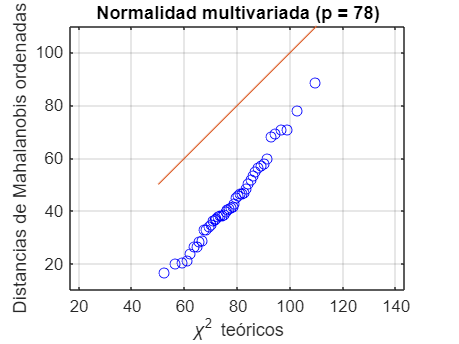


% Calcular distancias de Mahalanobis
D2 = zeros(n, 1);
for i = 1:n
    diff = X(i, :) - mu;
    D2(i) = diff * invS * diff';
end

% Cuantiles teóricos de chi-cuadrado con p grados de libertad
chi2_quant = chi2inv(((1:n)' - 0.5) / n, p);
D2_sorted = sort(D2);

% Graficar el Chi-square plot
figure;
plot(chi2_quant, D2_sorted, 'bo');
hold on;
refline(1, 0);  % línea identidad
xlabel('\chi^2 teóricos');
ylabel('Distancias de Mahalanobis ordenadas');
title(['Normalidad multivariada (p = ', num2str(p), ')']);
axis equal;
grid on;

bivariate normality

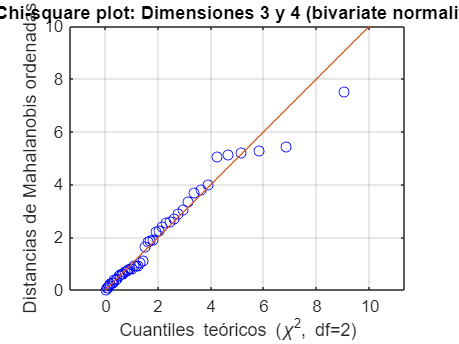

% Seleccionar dim 3 y 4
X_sub = X(:, [3 4]);  % n x 2

% Calcular vector de medias y matriz de covarianza
mean_vec = mean(X_sub);          % 1 x 2
cov_mat = cov(X_sub);            % 2 x 2
inv_cov = pinv(cov_mat);

% Calcular distancias de Mahalanobis
mahal_dist = zeros(n, 1);
for i = 1:n
    diff = X_sub(i, :) - mean_vec;
    mahal_dist(i) = diff * inv_cov * diff';
end

% Cuantiles teóricos de chi-cuadrado con 2 grados de libertad
chi2_q = chi2inv(((1:n)' - 0.5) / n, 2);  % para bivariado, df = 2

% Graficar Chi-square plot
figure;
plot(chi2_q, sort(mahal_dist), 'bo');
hold on;
refline(1, 0);  % línea identidad
xlabel('Cuantiles teóricos (\chi^2, df=2)');
ylabel('Distancias de Mahalanobis ordenadas');
title('Chi-square plot: Dimensiones 3 y 4 (bivariate normality)');
axis equal;
grid on;